datapath_all = ...
    {"/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230820_AChSensor_Slice_002_puffing_60X_puffing1345",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230820_AChSensor_Slice_003_puffing_60X_puffing1234",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230821_AChSensor_Slice_001_puffing_60X_puffing1234",...
    "/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230821_AChSensor_Slice_002_puffing_60X_puffing14",...
    }

datapath_all = 1×4 cell array
    {["/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230820_AChSensor_Slice_002_puffing_60X_puffing1345"]}    {["/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230820_AChSensor_Slice_003_puffing_60X_puffing1234"]}    {["/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230821_AChSensor_Slice_001_puffing_60X_puffing1234"]}    {["/Volumes/yaochen/Active/Pingchuan/2023Fall/puffing_SliceMode/20230821_AChSensor_Slice_002_puffing_60X_puffing14"]}




StateYao_file_all = ...
    {{'puffing3.mat','puffing4.mat','puffing5.mat'},...
    {'puffing1.mat','puffing2.mat','puffing3.mat','puffing4.mat'},...
    {'puffing1.mat','puffing2.mat','puffing3.mat','puffing4.mat',},...
    {'puffing1.mat','puffing4.mat',}...
    }

StateYao_file_all = 1×4 cell array
    {1×4 cell}    {1×4 cell}    {1×4 cell}    {1×2 cell}



summary_files = {};
summary_path = '/Users/pingchuanma/Desktop/ChenLab_Data/ACh_sensor_slice/puffing/';

puffing_acqs_all = ...
    {[97 133 170],...
    [20 54 95 133],...
    [25 59 101 149],...
    [23 135]...
    }

puffing_acqs_all = 1×4 cell array
    {[29 97 133 170]}    {[20 54 95 133]}    {[25 59 101 149]}    {[23 135]}


baseline_acq_num = 10; % how many acquisitions are used for either baseline start calculation
epoch_acq_num = 10; % epoch based response calculation
CyclePositions = 1;

FigureVisible = 'off'

FigureVisible = 'off'


load('/Volumes/yaochen/Active/Pingchuan/2023Fall/20230925_TestSliceTimestamp_001/Slice_intervals.mat')
slice_num = 3;
slice_time = slice_intervals_mean/60

slice_time = 0.0289

i_summary = 1;

for i_path = 1:length(datapath_all)

    cd(datapath_all{i_path})

    for i_file = 1:length(StateYao_file_all{i_path})

        load(StateYao_file_all{i_path}{i_file})
%         load("autonotes.mat") % previous how I determine the puffing time
        puffing_acq = puffing_acqs_all{i_path}(i_file);

        [intensity_values, lifetime_values, num_cell] = ExtractPuffingDataInSliceMode(stateYao);
%         [puffing_time] = DeterminePuffingTime(notebook, puffing_acq) % previous how I determine the puffing time
        All_acqs = stateYao.CyclePositions;
        AcqTime_original = stateYao.AcqTime;
        AcqTime_original = AcqTime_original - AcqTime_original(1);

        AcqTime = zeros(10*length(stateYao.AcqTime), 1);
        for i_slice_time = 1:10
            AcqTime(i_slice_time) = AcqTime_original(1) - slice_time*(10 - i_slice_time);
        end
        for i_time = 2:length(stateYao.AcqTime)
            if AcqTime_original(i_time) < 0
                AcqTime_original(i_time) = AcqTime_original(i_time) + 24*60;
            end
            if All_acqs(i_time) == puffing_acq + 1
                LastWrittenTime = DeterminePuffingTime_fromAD(puffing_acq);
            else
                if All_acqs(i_time)-1 < 10
                    LastFileNum = ['00', num2str(All_acqs(i_time)-1)];
                elseif All_acqs(i_time)-1 >=10 & All_acqs(i_time)-1<100
                    LastFileNum = ['0', num2str(All_acqs(i_time)-1)];
                else
                    LastFileNum = num2str(All_acqs(i_time)-1);
                end
                LastFileDir = dir([stateYao.baseName, 'FLIM', LastFileNum, '.mat']);
                if isempty(LastFileDir) == 1
                    LastWrittenTime = stateYao.AcqTime(i_time) - slice_time*10;
                else
                    LastWrittenTime = datevec(LastFileDir.date);
                    LastWrittenTime = LastWrittenTime(4)*60 + LastWrittenTime(5) + LastWrittenTime(6)/60;
                end
            end

            LastWrittenTime = LastWrittenTime - stateYao.AcqTime(1);

            if LastWrittenTime < 0
                LastWrittenTime = LastWrittenTime + 24*60;
            end

            DistributedTime = linspace(LastWrittenTime, AcqTime_original(i_time), 11);

            AcqTime((i_time-1)*10+1:(i_time-1)*10+10) = DistributedTime(2:11);


%             for i_slice_time = 1:10
%                 AcqTime((i_time-1)*10 + i_slice_time) = stateYao.AcqTime(i_time) - slice_time*(10 - i_slice_time);
%             end
        end


        [puffing_time] = DeterminePuffingTime_fromAD(puffing_acq);
        puffing_time = puffing_time - 0.1730/60; % determine puffing time by the written time of the puffing AD file minus the time (determined empirically)...
        % ...it takes between starting the puffing and writing of the AD file
        puffing_time = puffing_time - stateYao.AcqTime(1);
        if puffing_time < 0
            puffing_time = puffing_time + 24*60;
        end

%         puffing_acq = puffing_acqs_all{i_path}(i_file);
%         All_acqs = stateYao.CyclePositions;
%         [puffing_time] = DeterminePuffingTime_empirically(puffing_acq, All_acqs, AcqTime);

        BaseName = stateYao.baseName;

        SaveName = [summary_path, BaseName, StateYao_file_all{i_path}{i_file}(1:8), '.mat'];
        summary_files{i_summary} = SaveName;
        i_summary = i_summary+1;

        save(SaveName, 'intensity_values', 'lifetime_values', 'num_cell', 'puffing_time', 'AcqTime', 'BaseName', 'i_file');
    end
end


save([summary_path, 'summary_files.mat'], 'summary_files')



cd(summary_path)
load('summary_files.mat')

intensity_summary = [];
lifetime_summary = [];
sampling_rate = [];

for i =1:length(summary_files)
    load(summary_files{i})

    for i_slice = 1:length(AcqTime)/10
        sampling_rate = [sampling_rate (AcqTime((i-1)*10+10) - AcqTime((i-1)*10+1))/10];
    end


%     [baseline_change_lifetime, puffing_change_lifetime, baseline_change_intensity, puffing_change_intensity] = CalcPuffing(lifetime_values, intensity_values, puffing_time, AcqTime, num_cell, baseline_acq_num, BaseName, summary_files{i}(end-11:end-4), FigureVisible);
%     intensity_summary = [intensity_summary; ([baseline_change_intensity puffing_change_intensity])];
%     lifetime_summary = [lifetime_summary; ([baseline_change_lifetime puffing_change_lifetime])];


end

1/(mean(sampling_rate)*60)

ans = 0.7102

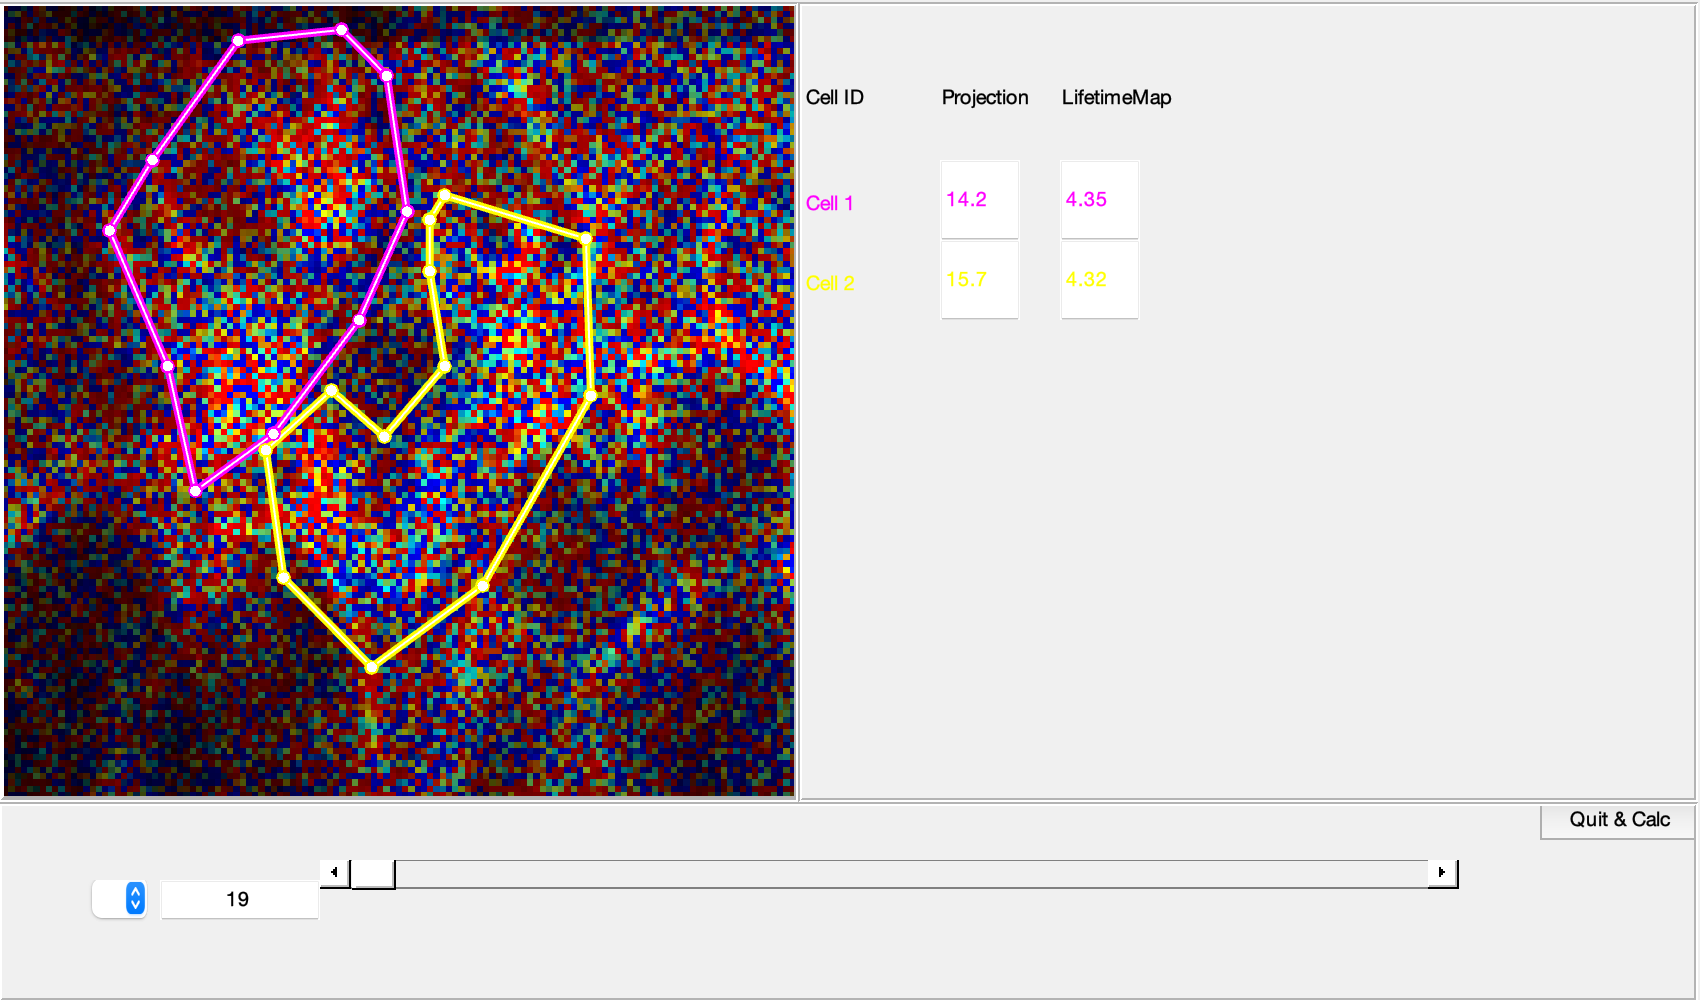

cell_index_all = {};

for i_path = 1%:length(datapath_all)

    cd(datapath_all{i_path})

    for i_file = 1%:length(StateYao_file_all{i_path})

        load(StateYao_file_all{i_path}{i_file})

        Yao_launchGui
%         display([stateYao.baseName, '_', StateYao_file_all{i_path}{i_file}])
%         prompt1 = "Give the index of the cell you want to include";
%         cell_index = input(prompt1);
%         cell_index_all{i_path}{i_file} = cell_index;


    end
end

cell_index_all2 = {};
i_puffing = 1;

for i_path = 1:length(datapath_all)
    for i_file = 1:length(StateYao_file_all{i_path})
        cell_index_all2{i_puffing} = cell_index_all{i_path}{i_file};
        i_puffing = i_puffing + 1;
    end
end

cd(summary_path)
load('summary_files.mat')
load('selcted_cell_index2.mat')

intensity_summary = [];
lifetime_summary = [];
AcqTime_aligned_all = {};
Lifetime_aligned_all = {};
Intensity_aligned_all = {};

for i =1:length(summary_files)
    load(summary_files{i})

    AcqTime_aligned = AcqTime - puffing_time;
    aligned_plot_index = find(AcqTime_aligned >= -2 & AcqTime_aligned <3);
    AcqTime_aligned_all{i} = AcqTime_aligned(aligned_plot_index);
    Lifetime_aligned_all{i} = lifetime_values{1}(aligned_plot_index, cell_index_all2{i});
    Intensity_aligned_all{i} = intensity_values{1}(aligned_plot_index, cell_index_all2{i});


    [baseline_change_lifetime, puffing_change_lifetime, baseline_change_intensity, puffing_change_intensity] = CalcPuffing(lifetime_values, intensity_values, puffing_time, AcqTime, num_cell, baseline_acq_num, BaseName, summary_files{i}(end-11:end-4), FigureVisible);
    intensity_summary = [intensity_summary; ([baseline_change_intensity(cell_index_all2{i}) puffing_change_intensity(cell_index_all2{i})])];
    lifetime_summary = [lifetime_summary; ([baseline_change_lifetime(cell_index_all2{i}) puffing_change_lifetime(cell_index_all2{i})])];
end

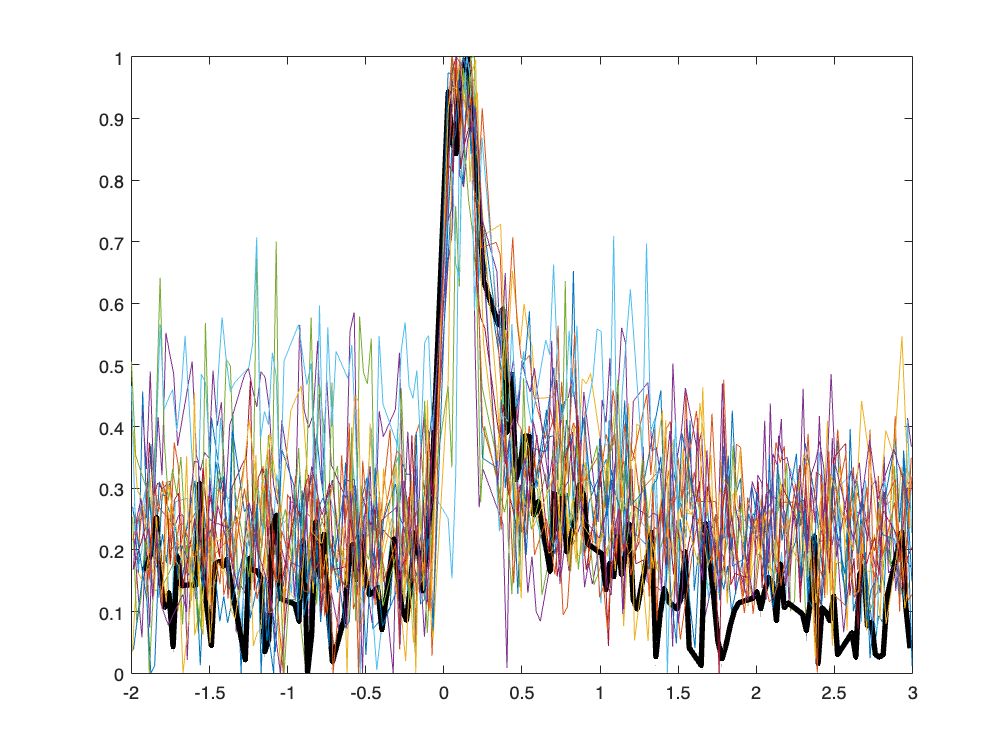

figure

for i = 1:13
    load(summary_files{i})
    for j = 1:size(Lifetime_aligned_all{i}, 2)
        plot_max = max(Lifetime_aligned_all{i}(:,j));
        plot_min = min(Lifetime_aligned_all{i}(:,j));
        plot_trace = (Lifetime_aligned_all{i}(:,j) - plot_min)/(plot_max - plot_min);

        if BaseName == '20230820_AChSensor_Slice_003' & i_file == 2
        
            plot(AcqTime_aligned_all{i}, plot_trace, 'LineWidth', 3, 'Color', 'k')
        else
            plot(AcqTime_aligned_all{i}, plot_trace)
        end
        hold on
    end
end

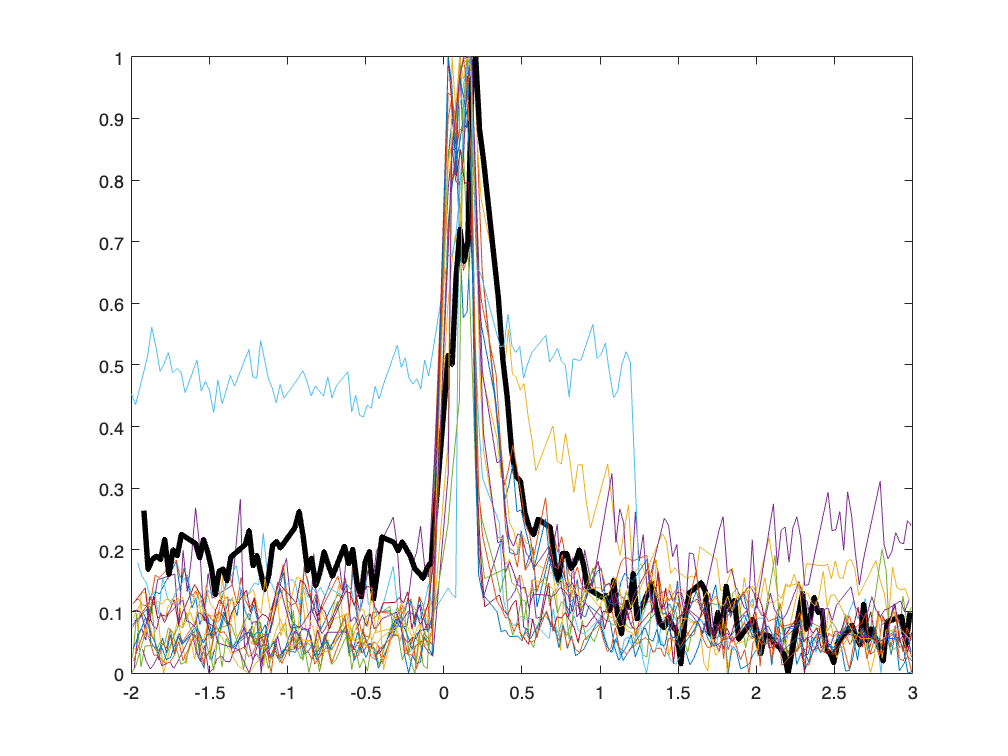

figure

for i = 1:13
    load(summary_files{i})
    for j = 1:size(Lifetime_aligned_all{i}, 2)
        plot_max = max(Intensity_aligned_all{i}(:,j));
        plot_min = min(Intensity_aligned_all{i}(:,j));
        plot_trace = (Intensity_aligned_all{i}(:,j) - plot_min)/(plot_max - plot_min);

        if BaseName == '20230820_AChSensor_Slice_003' & i_file == 2
        
            plot(AcqTime_aligned_all{i}, plot_trace, 'LineWidth', 3, 'Color', 'k')
        else
            plot(AcqTime_aligned_all{i}, plot_trace)
        end
        hold on
    end
end

puffing_index = find(stateYao.CyclePositions == 134);

createdMask = boundarymask(stateYao.images.I_ROI_stack{1}{puffing_index});
savepath = '/Users/pingchuanma/Desktop/ChenLab_Data/ACh_sensor_slice/puffing/puffing4_trace_check';
mkdir(savepath)


B = imoverlay(spc.rgbLifetimes{1}, createdMask);
f = figure('visible','off')

f =   Figure (18) with properties:

      Number: 18
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [-880 800 560 420]
       Units: 'pixels'

  Show all properties


image(B)
image_name = [savepath,'/0820-003-puffing4-', num2str(i_slice),'.png']

image_name = '/Users/pingchuanma/Desktop/ChenLab_Data/ACh_sensor_slice/puffing/puffing4_trace_check/0820-003-puffing4-10.png'

title_name = ['0820-003-puffing4-slice', num2str(i_slice),'.png']

title_name = '0820-003-puffing4-slice10.png'

title(title_name)
saveas(f, image_name)
i_slice = i_slice+1;


% for plotting the trace
cd(summary_path)
load('20230820_AChSensor_Slice_003puffing2.mat')

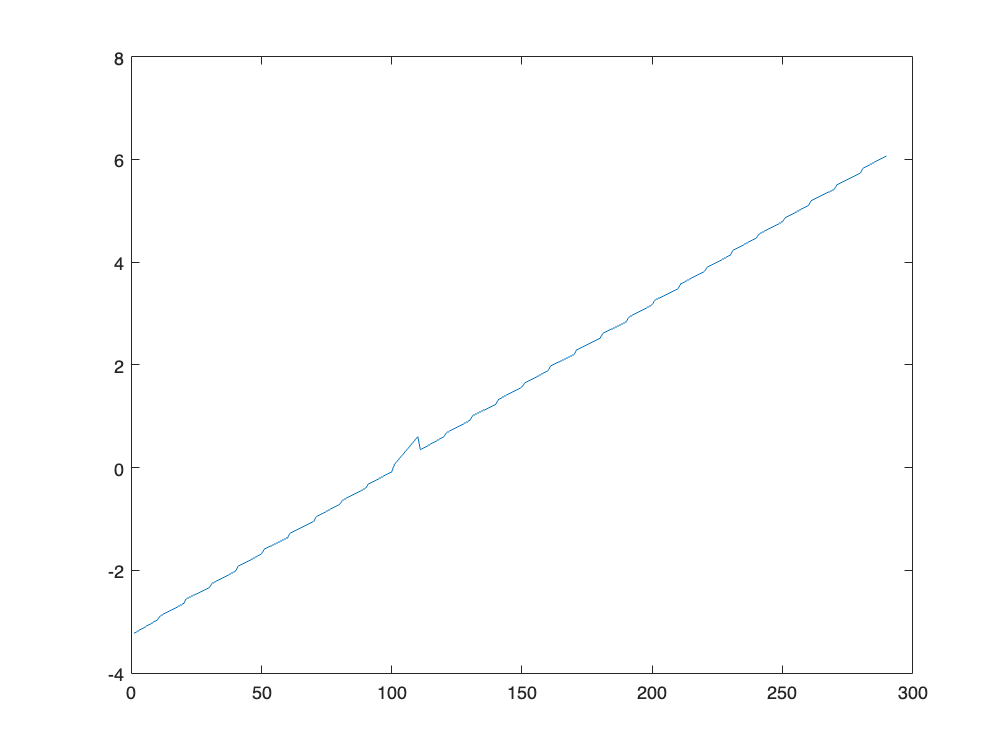

AcqTime_aligned = AcqTime - puffing_time;
figure
plot(AcqTime_aligned)

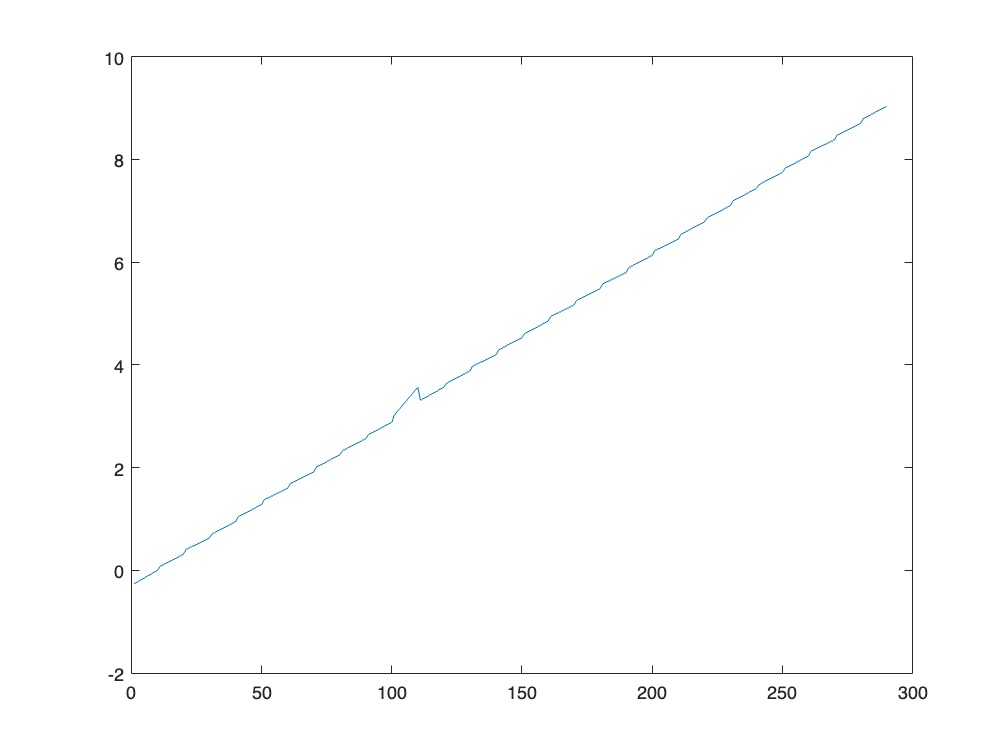

figure
plot(AcqTime)

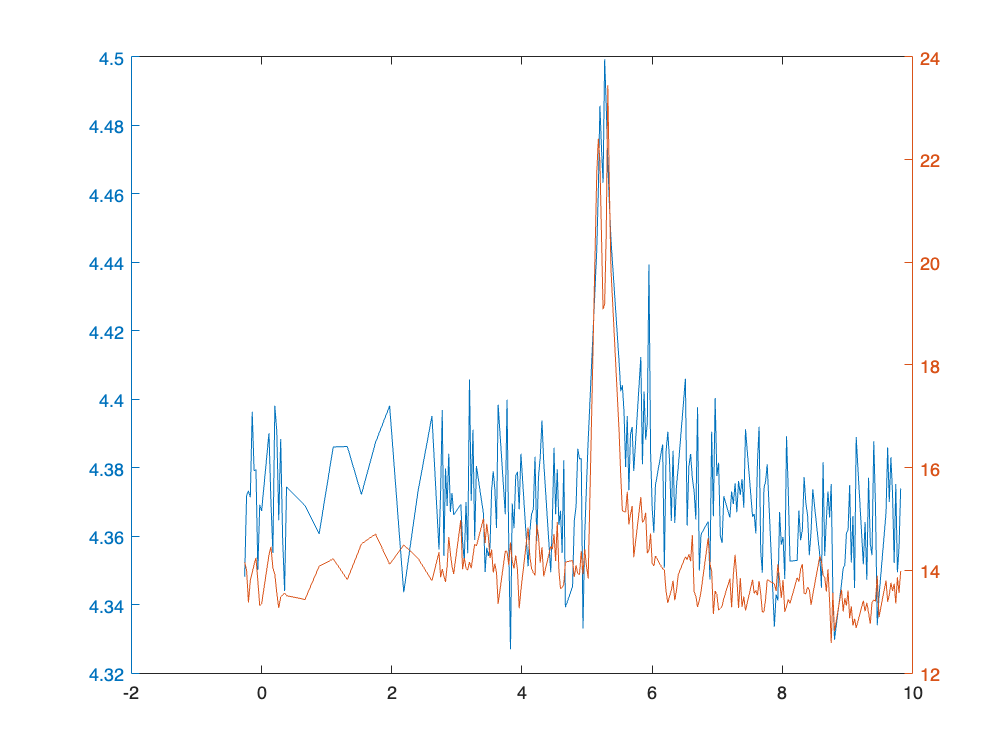

figure
yyaxis left
plot(AcqTime, lifetime_values{1}(:,1))
yyaxis right
plot(AcqTime, intensity_values{1}(:,1))


% only plot about 1 min before puffing and 2 mins after puffing; puffing
% time is 3.5695, start plot around 2.5, which is about index 80; end plot
% around 5.6, which is about index 171

AcqTime_plot = AcqTime(80:171);
puffing_time_plot = puffing_time - AcqTime_plot(1)

puffing_time_plot = 1.1159

puffing_time_end_plot = puffing_time_plot + 10/60

puffing_time_end_plot = 1.2826

AcqTime_plot = AcqTime_plot - AcqTime_plot(1);

intensity_plot = intensity_values{1}(80:171, 1);
lifetime_plot = lifetime_values{1}(80:171, 1);

% use AcqTime_plot, puffing_time_plot, intensity_plot, and lifetime_plot
% for plotting in prism

% for plotting the trace
load('20230820_AChSensor_Slice_002puffing1.mat')


% only plot about 1 min before puffing and 2 mins after puffing; puffing
% time is 6.6799, start plot around 5.6799, which is about index 165; end plot
% around 8.7, which is about index 254

AcqTime_plot = AcqTime(165:254);
puffing_time_plot = puffing_time - AcqTime_plot(1)

puffing_time_plot = 1.0466

puffing_time_end_plot = puffing_time_plot + 10/60

puffing_time_end_plot = 1.2133

AcqTime_plot = AcqTime_plot - AcqTime_plot(1);

intensity_plot = intensity_values{1}(165:254, 1);
lifetime_plot = lifetime_values{1}(165:254, 1);

% use AcqTime_plot, puffing_time_plot, intensity_plot, and lifetime_plot
% for plotting in prism


% for plotting the trace
load('20230820_AChSensor_Slice_003puffing4.mat')


% only plot about 1 min before puffing and 2 mins after puffing; puffing
% time is 2.9364, start plot around 1.9, which is about index 69; end plot
% around 5, which is about index 166

AcqTime_plot = AcqTime(69:166);
puffing_time_plot = puffing_time - AcqTime_plot(1)

puffing_time_plot = 1.0447

puffing_time_end_plot = puffing_time_plot + 10/60

puffing_time_end_plot = 1.2114

AcqTime_plot = AcqTime_plot - AcqTime_plot(1);

intensity_plot = intensity_values{1}(69:166, 1);
lifetime_plot = lifetime_values{1}(69:166, 1);

% use AcqTime_plot, puffing_time_plot, intensity_plot, and lifetime_plot
% for plotting in prism


% mannually change the value of one dataset
load('20230821_AChSensor_Slice_001puffing2.mat')

baseline_mean = mean(lifetime_values{1}(1:10,4))

baseline_mean = 4.3464


puffing_max_index = 105;
puffing_max = lifetime_values{1}(puffing_max_index,4)

puffing_max = 4.4823


puffing_response = puffing_max - baseline_mean

puffing_response = 0.1359

% detarmine the puffing time

puffing_diff = [];

i_summary = 1;

for i_path = 1:length(datapath_all)

    cd(datapath_all{i_path})

    for i_file = 1:length(StateYao_file_all{i_path})

%         load(StateYao_file_all{i_path}{i_file})
        load("autonotes.mat") % previous how I determine the puffing time
        puffing_acq = puffing_acqs_all{i_path}(i_file);
        [puffing_time1] = DeterminePuffingTime_fromAD(puffing_acq);

%         [intensity_values, lifetime_values, num_cell] = ExtractPuffingDataInSliceMode(stateYao)
        [puffing_time2] = DeterminePuffingTime(notebook, puffing_acq); % previous how I determine the puffing time
        puffing_diff = [puffing_diff puffing_time2 - puffing_time1];
        
    end
end

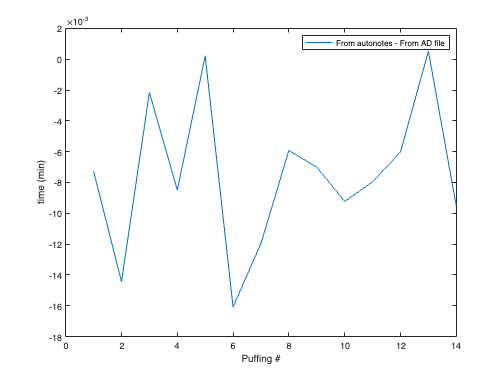


figure
plot(puffing_diff)
xlabel('Puffing #')
ylabel('time (min)')
legend({'From autonotes - From AD file'})

function [puffing_time] = DeterminePuffingTime(notebook, puffing_acq)

for i_note = 1:length(notebook)

    WholeString = notebook{i_note};
    PuffingString = ['Acq # ', num2str(puffing_acq)];

    if contains(WholeString, PuffingString)
        puffing_time_vector = datevec(notebook{i_note}(1:8));
        puffing_time_vector = puffing_time_vector(4:6);
        puffing_time = puffing_time_vector(1)*60+puffing_time_vector(2)+puffing_time_vector(3)/60;
    end
end
end
% -----------------------------------------------------
function [puffing_time] = DeterminePuffingTime_fromAD(puffing_acq)

AD_file = ['AD7_', num2str(puffing_acq), '.mat'];

AD_data = load(AD_file);
eval(['AD_time = AD_data.AD7_', num2str(puffing_acq), '.timeStamp;'])
TimeInDays = floor(AD_time/(24*3600));
TimeInHours = floor((AD_time - TimeInDays*24*3600)/3600);
TimeInMinutes = floor((AD_time - TimeInDays*24*3600 - TimeInHours*3600)/60);
TimeInSeconds = AD_time - TimeInDays*24*3600 - TimeInHours*3600 - TimeInMinutes*60;

puffing_time = TimeInHours*60 + TimeInMinutes + TimeInSeconds/60;


end
% ---------------------------------------------
function [intensity_values, lifetime_values, num_cell] = ExtractPuffingDataInSliceMode(stateYao)

num_cycleposition = size(stateYao.Results.spc_calculateROIvals.Projection, 1);
num_slice = size(stateYao.Results.spc_calculateROIvals.Projection, 2);
num_acq = zeros(1, num_cycleposition);
num_cell = zeros(1, num_cycleposition);

for i = 1:num_cycleposition
    num_acq(i) = size(stateYao.Results.spc_calculateROIvals.Projection{i,1}, 1);
    num_cell(i) = length(stateYao.Results.spc_calculateROIvals.Projection{i,1}{1});
end

lifetime_values = {};
intensity_values = {};

for i = 1:num_cycleposition
    lifetime_values{i} = zeros(num_slice * num_acq(i),1);
    intensity_values{i} = zeros(num_slice * num_acq(i),1);

    i_index = 1;

    for j = 1:num_acq(i)

        for k = 1:num_slice

            for i_cell = 1:num_cell(i)
                lifetime_values{i}(i_index,i_cell) = stateYao.Results.spc_calculateROIvals.LifetimeMap{i,k}{j}(i_cell);
                intensity_values{i}(i_index,i_cell) = stateYao.Results.spc_calculateROIvals.Projection{i,k}{j}(i_cell);
            end

            i_index = i_index + 1;
        end
    end
end

end
% ---------------------------------------------
function [puffing_time] = DeterminePuffingTime_empirically(puffing_acq, All_acqs, AcqTime)

puffing_index = max(find(All_acqs < puffing_acq));
puffing_time = mean([AcqTime(puffing_index*10) AcqTime(puffing_index*10+1)]);


end
% ---------------------------------------------
function [baseline_change_lifetime, puffing_change_lifetime, baseline_change_intensity, puffing_change_intensity] = CalcPuffing(values1, values2, puffing_time, AcqTime, num_cell, baseline_acq_num, BaseName, i_file, FigureVisible)

baseline_change_lifetime = zeros(num_cell, 1);
puffing_change_lifetime = zeros(num_cell, 1);

baseline_change_intensity = zeros(num_cell, 1);
puffing_change_intensity = zeros(num_cell, 1);


for i = 1:length(AcqTime)

    if AcqTime(i) > puffing_time

        break
    end
end

for j = 1:num_cell

    baseline_lifetime = mean(values1{1}(1:baseline_acq_num, j));
    baseline_response_lifetime = max(values1{1}(baseline_acq_num+1:i-1, j));
    baseline_response_index_lifetime = mean(find(values1{1}(:,j) == baseline_response_lifetime));

    puffing_response_lifetime = max(values1{1}(i:end, j));
    puffing_index_lifetime = mean(find(values1{1}(:,j) == puffing_response_lifetime));

    baseline_change_lifetime(j) = baseline_response_lifetime - baseline_lifetime;
    puffing_change_lifetime(j) = puffing_response_lifetime - baseline_lifetime;


    baseline_intensity = mean(values2{1}(1:baseline_acq_num, j));
    baseline_response_intensity = max(values2{1}(baseline_acq_num+1:i-1, j));
    baseline_response_index_intensity = mean(find(values2{1}(:,j) == baseline_response_intensity));

    puffing_response_intensity = max(values2{1}(i:end, j));
    puffing_index_intensity = mean(find(values2{1}(:,j) == puffing_response_intensity));

    baseline_change_intensity(j) = (baseline_response_intensity - baseline_intensity)/baseline_intensity;
    puffing_change_intensity(j) = (puffing_response_intensity - baseline_intensity)/baseline_intensity;

    figureName = [BaseName, '_', i_file, '_Cell', num2str(j), '.png'];

    figure('Visible', FigureVisible)
    subplot(2,1,1)
    scatter(AcqTime, values1{1}(:,j), 15, 'filled')
    hold on
    yline(baseline_lifetime)
    hold on
    xline([puffing_time puffing_time+10/60])
    hold on
    scatter(AcqTime([baseline_response_index_lifetime puffing_index_lifetime]), values1{1}([baseline_response_index_lifetime puffing_index_lifetime],j))
%     text(AcqTime(baseline_response_index_lifetime), values1{1}(baseline_response_index_lifetime,j), num2str(AcqTime(baseline_response_index_lifetime)*60))
    title('Lifetime')
    ylabel('Lifetime (ns)')
    hold off
    subplot(2,1,2)
    scatter(AcqTime, values2{1}(:,j), 15, 'filled')
    hold on
    yline(baseline_intensity)
    hold on
    xline([puffing_time puffing_time+10/60])
    hold on
    scatter(AcqTime([baseline_response_index_intensity puffing_index_intensity]), values2{1}([baseline_response_index_intensity puffing_index_intensity],j))
    title('Intensity')
    ylabel('Intensity (photons/pixel)')
    xlabel('Time (min)')
    hold off

    saveas(gcf, figureName)



end
end





